### Señal continua:= x(t)

### Señal discreta:= x[t]

syms t
%variable simbólica
y_symb=cos(t)

$$y\_symb = \cos\left(t\right)$$

y_fh=@(t) cos(t)

y_fh = function_handle with value:
    @(t)cos(t)


y_fh([5,8,10])

ans =     0.2837   -0.1455   -0.8391


subs(y_symb,t,[5 8 10])

$$ans = \left(\begin{array}{ccc} \cos\left(5\right) & \cos\left(8\right) & \cos\left(10\right) \end{array}\right)$$

y_3=y_symb+sin(t)+exp(-t)

$$y\_3 = {\mathrm{e}}^{-t}+\cos\left(t\right)+\sin\left(t\right)$$

diff(y_3)

$$ans = \cos\left(t\right)-{\mathrm{e}}^{-t}-\sin\left(t\right)$$

int(y_3,[0 1])

$$ans = \sin\left(1\right)-{\mathrm{e}}^{-1}-\cos\left(1\right)+2$$

int(y_3,t)

$$ans = -{\mathrm{e}}^{-t}-\sqrt{2}\,\cos\left(t+\frac{\pi }{4}\right)$$

y_3_fh=matlabFunction(y_3)

y_3_fh = function_handle with value:
    @(t)exp(-t)+cos(t)+sin(t)


y_3_fh([5 8 10])

ans =    -0.6685    0.8442   -1.3830


## Funciones discretas y continuas

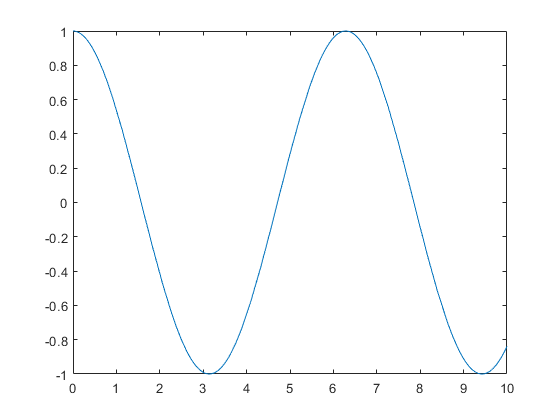

figure
fplot(y_symb,[0,10])

figure
fplot(y_fh,[0,10])

t_disc=0:10 

t_disc =      0     1     2     3     4     5     6     7     8     9    10


y_disc=y_fh(t_disc)

y_disc =     1.0000    0.5403   -0.4161   -0.9900   -0.6536    0.2837    0.9602    0.7539   -0.1455   -0.9111   -0.8391


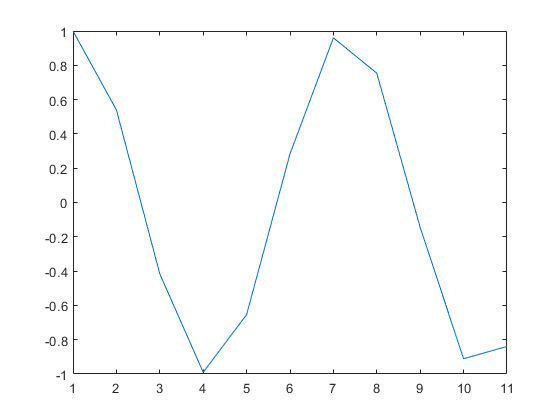

figure
plot(y_disc)

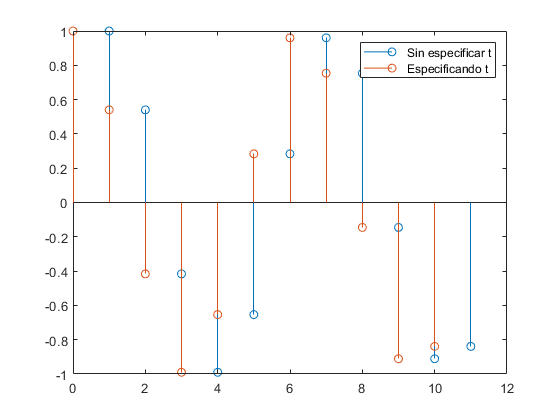

figure
stem(y_disc)
hold on

stem(t_disc,y_disc)
hold off
legend("Sin especificar t","Especificando t")

t_disc=0:0.1:10

t_disc =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


y_disc=y_fh(t_disc)

y_disc =     1.0000    0.9950    0.9801    0.9553    0.9211    0.8776    0.8253    0.7648    0.6967    0.6216    0.5403    0.4536    0.3624    0.2675    0.1700    0.0707   -0.0292   -0.1288   -0.2272   -0.3233   -0.4161   -0.5048   -0.5885   -0.6663   -0.7374   -0.8011   -0.8569   -0.9041   -0.9422   -0.9710   -0.9900   -0.9991   -0.9983   -0.9875   -0.9668   -0.9365   -0.8968   -0.8481   -0.7910   -0.7259   -0.6536   -0.5748   -0.4903   -0.4008   -0.3073   -0.2108   -0.1122   -0.0124    0.0875    0.1865


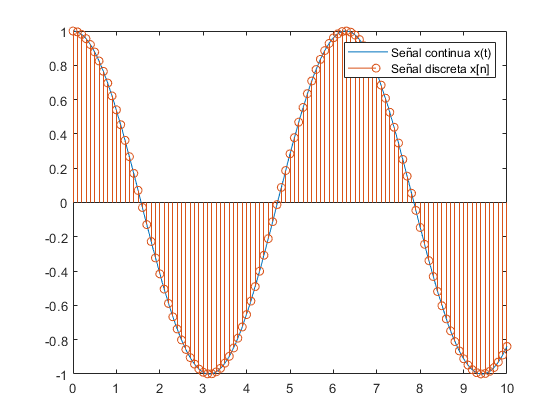

figure
fplot(y_fh,[0 10])
hold on
stem(t_disc,y_disc)
hold off
legend("Señal continua x(t)","Señal discreta x[n]")

### Ejercicio 1

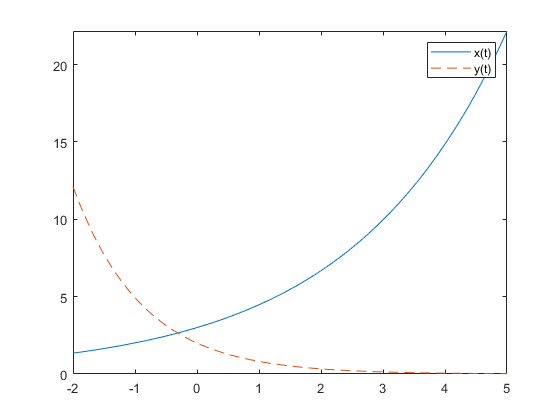

syms t
x_1=3*exp(0.4*t);

y_1=2*exp(-0.9*t);

figure
fplot(x_1,[-2 5])
hold on
fplot(y_1,[-2 5],"LineStyle","--")
hold off
legend("x(t)","y(t)")

### Ejercicio 2

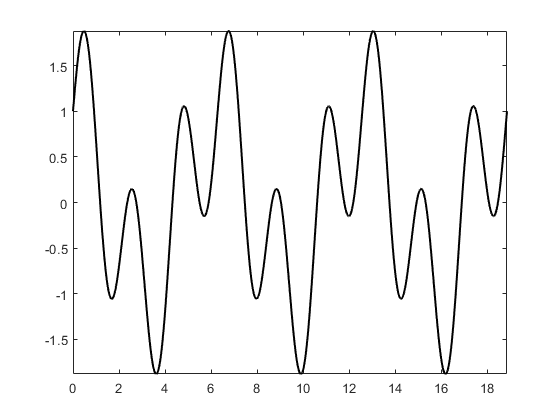

syms t
x_2=cos(t) +sin(3*t);

figure
fplot(x_2,[0 6*pi],"Color","black","LineWidth",1.5)

## Formas básicas de la onda

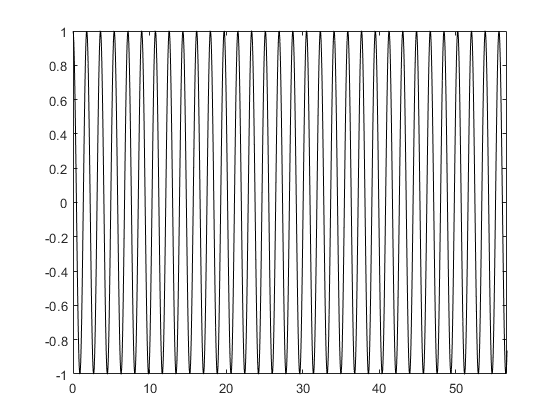

syms t
a=3.5;
b=2.8;
t0=0;
tf=56.7 ;   
c=0;
x(t)=cos(a*t) + sin (b*t)*c+5;
%hue hue hue
%cuack
figure
fplot(x,[t0 tf],"Color","black")

%Ire que boneto

### Ejercicio 3

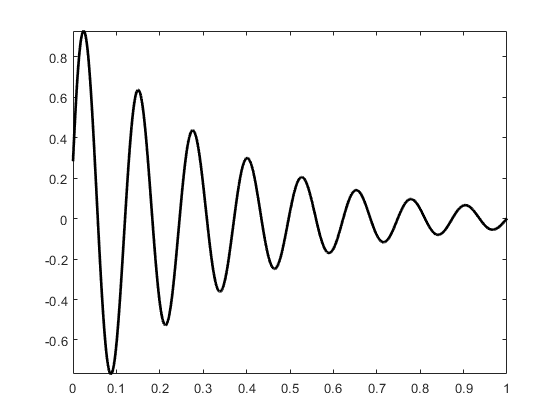

syms t
t0=0;
tf=1;
theta=5;
omega_0=50;
C=1;
r=-3;
figure
x_3=C*exp(r*t)*cos(omega_0*t+theta);
fplot(x_3,[t0 tf],"Color","black","LineWidth",2)

## Gráfica de la función seno

t=0:0.01:100;
x_t=sin(t);
y_t=cos(t)

y_t =     1.0000    1.0000    0.9998    0.9996    0.9992    0.9988    0.9982    0.9976    0.9968    0.9960    0.9950    0.9940    0.9928    0.9916    0.9902    0.9888    0.9872    0.9856    0.9838    0.9820    0.9801    0.9780    0.9759    0.9737    0.9713    0.9689    0.9664    0.9638    0.9611    0.9582    0.9553    0.9523    0.9492    0.9460    0.9428    0.9394    0.9359    0.9323    0.9287    0.9249    0.9211    0.9171    0.9131    0.9090    0.9048    0.9004    0.8961    0.8916    0.8870    0.8823


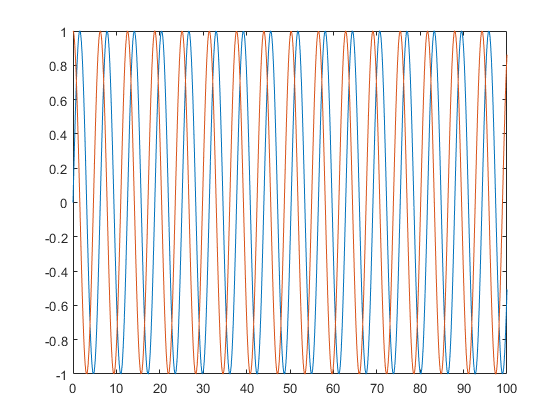

figure
plot(t,x_t)
hold on
plot(t,y_t)
hold off